## Landing Gear Mechanism

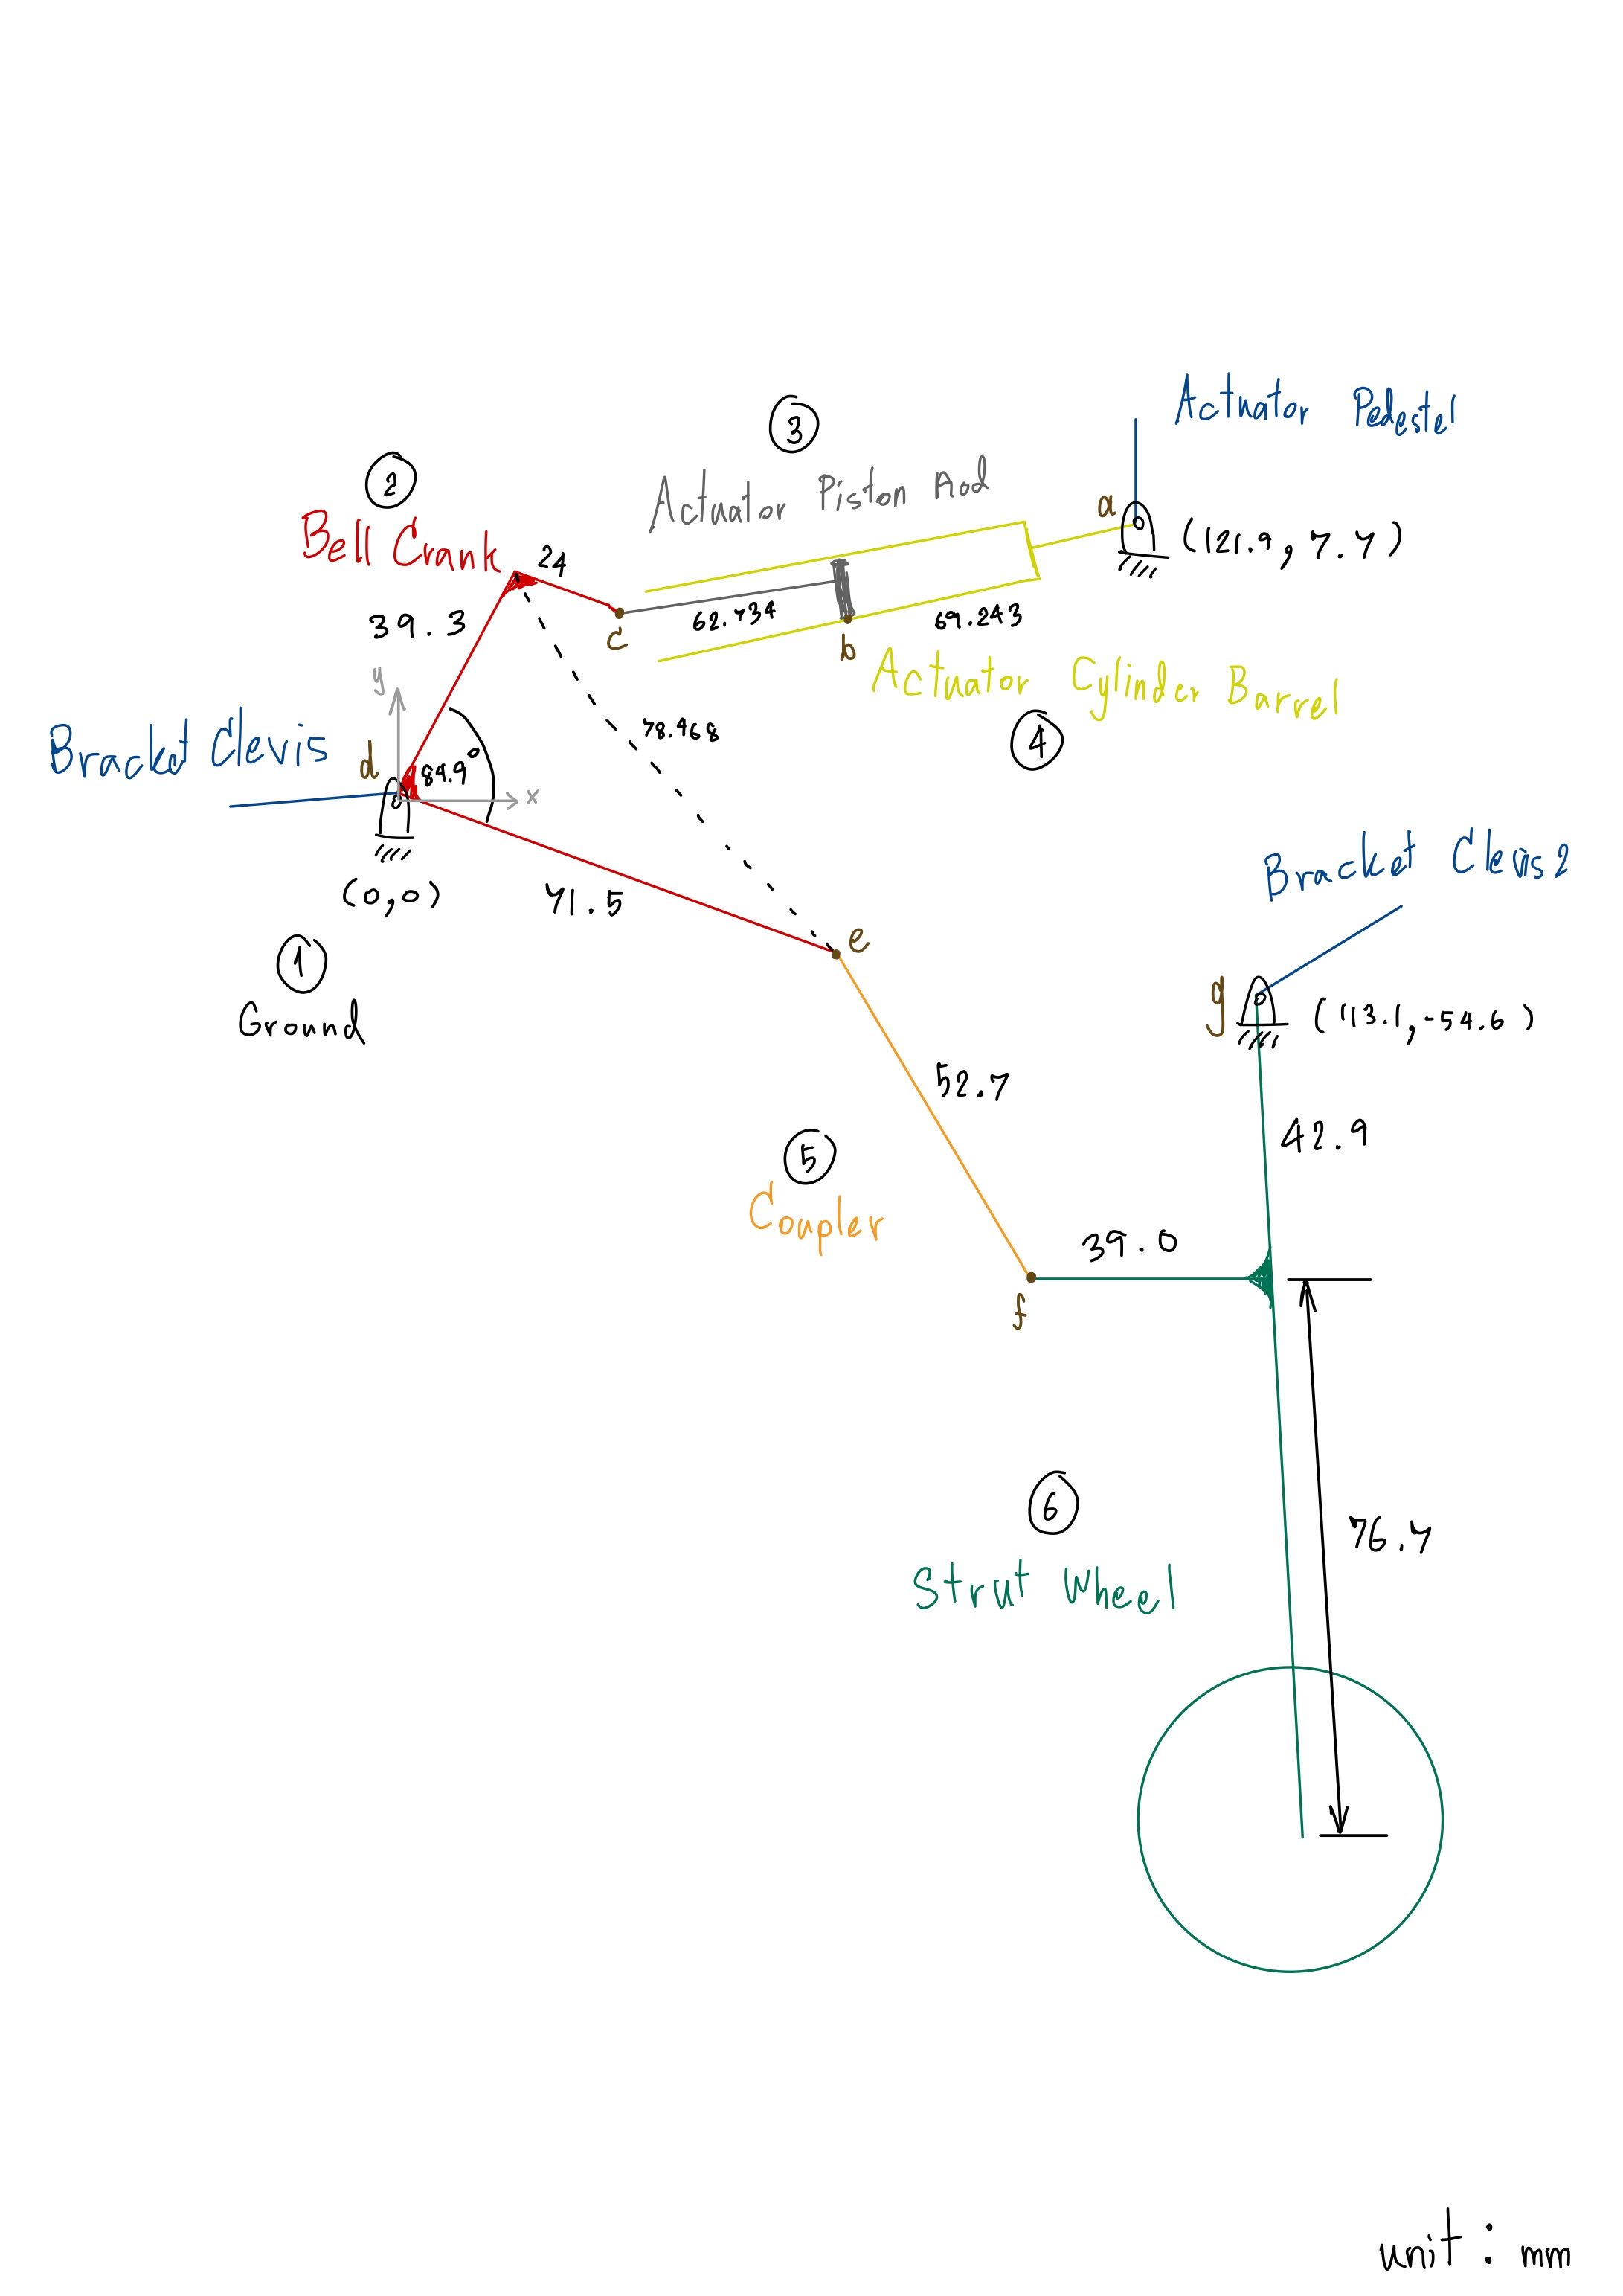

clear all
close all
clc

theta2 = sym("theta_2");
theta3 = sym("theta_3");
theta5 = sym("theta_5");
theta6 = sym("theta_6");

### Dimensions

l2_de = 71.5;
l2_dR = 39.3;
l2_Rc = 24;
l5 = 57.2;
l1_dg = sqrt(113.1^2+54.6^2);
l6_fg = sqrt(39^2+42.9^2);
l6_gP = 119.6;
l6_gQ = 42.9;
l6_fQ = 39.0;
L_cyl = 69.243;

O2x = 0; O2y = 0;
O6x = 113.1; O6y = -54.6;
O3x = 121.9; O3y = 7.7;

### **Equation of Motions**

ex = l2_de * cos(theta2);
ey = l2_de * sin(theta2);
fx = O6x + l6_fg * cos(theta6);
fy = O6y + l6_fg * sin(theta6);
cylx = O3x + L_cyl * cos(theta3);
cyly = O3y + L_cyl * sin(theta3);

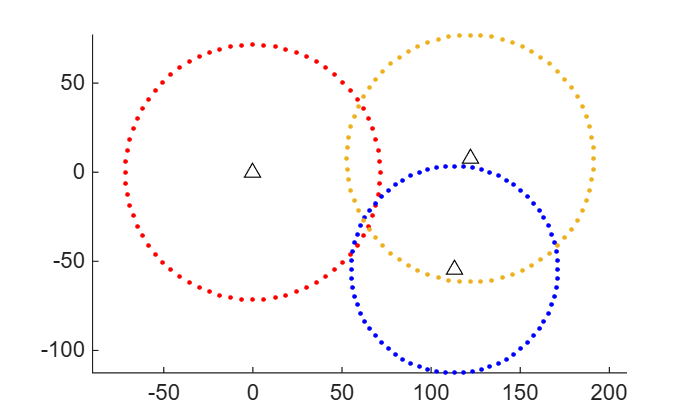

figure()

theta_to_plot = deg2rad(0:5:360);
hold on
plot(O2x,O2y,"^k")
plot(O6x,O6y,"^k")
plot(O3x,O3y,"^k")

plot(subs(ex,theta_to_plot),subs(ey,theta_to_plot),".r")
plot(subs(fx,theta_to_plot),subs(fy,theta_to_plot),".b")
plot(subs(cylx,theta_to_plot),subs(cyly,theta_to_plot),".","Color", "#EDB120")
hold off
axis equal

eq1 = fx == ex + l5*cos(theta5);
eq2 = fy == ey + l5*sin(theta5);

sol = solve([eq1 eq2],[theta5 theta6]);

theta5_sol = sol.theta_5(1);
theta6_sol = sol.theta_6(1);

Qx = O6x + l6_gQ * cos(theta6_sol + atan(l6_fQ/l6_gQ));
Qy = O6y + l6_gQ * sin(theta6_sol + atan(l6_fQ/l6_gQ));
Px = O6x + l6_gP * cos(theta6_sol + atan(l6_fQ/l6_gQ));
Py = O6y + l6_gP * sin(theta6_sol + atan(l6_fQ/l6_gQ));
Rx = O2x + l2_dR * cos(theta2 + deg2rad(84.9));
Ry = O2y + l2_dR * sin(theta2 + deg2rad(84.9));
Cx = Rx + l2_Rc * cos(theta2 + deg2rad(-(180 - 84.9 - 82.045)));
Cy = Ry + l2_Rc * sin(theta2 + deg2rad(-(180 - 84.9 - 82.045)));


fxNew = subs(fx,theta6,theta6_sol);
fyNew = subs(fy,theta6,theta6_sol);

### Angle Verifying

L_CAD_retracted = 78.243;
L_CAD_extended  = 123.976;

th = deg2rad(-180:0.1:180);

theta6_f = matlabFunction(theta6_sol, 'Vars', theta2);
Cx_f     = matlabFunction(Cx, 'Vars', theta2);
Cy_f     = matlabFunction(Cy, 'Vars', theta2);

vals = theta6_f(th);
ok   = abs(imag(vals)) < 1e-9 & ~isnan(vals);

Lact = sqrt((Cx_f(th) - O3x).^2 + (Cy_f(th) - O3y).^2);

idx = find(ok);
brk = find(diff(idx) > 1);
seg_start = [1, brk + 1];
seg_end   = [brk, numel(idx)];

theta_start = NaN;
theta_end   = NaN;

for k = 1:numel(seg_start)
    seg = idx(seg_start(k):seg_end(k));
    fprintf('Range %d: theta2 = %.1f° to %.1f° | L_act = %.1f to %.1f mm\n', ...
        k, rad2deg(th(seg(1))), rad2deg(th(seg(end))), min(Lact(seg)), max(Lact(seg)));

    if min(Lact(seg)) <= L_CAD_extended + 0.5 && max(Lact(seg)) >= L_CAD_extended - 0.5
        [e1, i1] = min(abs(Lact(seg) - L_CAD_retracted));
        [~,  i2] = min(abs(Lact(seg) - L_CAD_extended));
        a = th(seg(i1));
        b = th(seg(i2));
        theta_start = min(a, b);
        theta_end   = max(a, b);
    end
end

Range 1: theta2 = -90.6° to 39.1° | L_act = 79.0 to 127.3 mm



if isnan(theta_start)
    figure
    plot(rad2deg(th(ok)), Lact(ok), '.'); hold on
    yline(L_CAD_retracted, 'r'); yline(L_CAD_extended, 'g');
    xlabel('\theta_2 [deg]'); ylabel('L_{act} [mm]'); grid on
end

fprintf('\n[ Result ]\n');


[ Result ]


fprintf('Retracted: theta2 = %.2f°\n', rad2deg(theta_start));

Retracted: theta2 = -47.80°


fprintf('Extended : theta2 = %.2f°\n', rad2deg(theta_end));

Extended : theta2 = 34.50°


### Input-Output Analysis

L_act_sym = sqrt((Cx - O3x)^2 + (Cy - O3y)^2);
L0 = double(subs(L_act_sym, theta2, theta_start));
s_sym     = L_act_sym - L0;

phi_sym = theta6_sol + atan(l6_fQ/l6_gQ);

disp('=============== Governing Equations ===============')

=============== Governing Equations ===============


disp('Loop closure (Loop of Link 2-5-6):')

Loop closure (Loop of Link 2-5-6):


disp(eq1)

$$\frac{4079815695569725\,\cos\left(\theta_{6}\right)}{70368744177664}+\frac{1131}{10}=\frac{143\,\cos\left(\theta_{2}\right)}{2}+\frac{286\,\cos\left(\theta_{5}\right)}{5}$$

disp(eq2)

$$\frac{4079815695569725\,\sin\left(\theta_{6}\right)}{70368744177664}-\frac{273}{5}=\frac{143\,\sin\left(\theta_{2}\right)}{2}+\frac{286\,\sin\left(\theta_{5}\right)}{5}$$

disp('Input: Actuator length  L_act(theta2) = |O3 -> C|, stroke s = L_act - L0')

Input: Actuator length  L_act(theta2) = |O3 -> C|, stroke s = L_act - L0


disp(vpa(s_sym, 5))

$$\sqrt{{\left(39.3\,\sin\left(\theta_{2}+1.4818\right)+24.0\,\sin\left(\theta_{2}-0.22785\right)-7.7\right)}^{2}+{\left(39.3\,\cos\left(\theta_{2}+1.4818\right)+24.0\,\cos\left(\theta_{2}-0.22785\right)-121.9\right)}^{2}}-79.022$$

disp('Output: Strut angle  phi = theta6 + atan(l6_fQ / l6_gQ)')

Output: Strut angle  phi = theta6 + atan(l6_fQ / l6_gQ)


disp('====================================================')

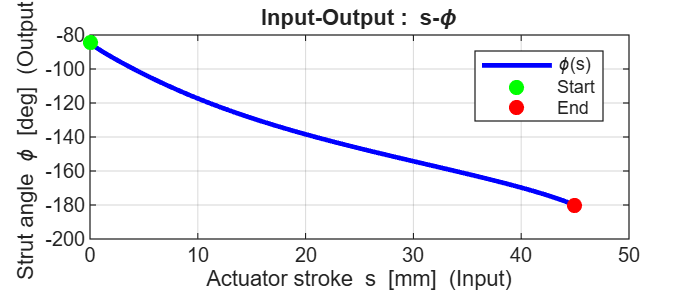


s_f = matlabFunction(s_sym, 'Vars', theta2);
phi_f = matlabFunction(phi_sym, 'Vars', theta2);

th_a = linspace(theta_start, theta_end, 300);
s_a = real(s_f(th_a));                     
phi_a = rad2deg(unwrap(real(phi_f(th_a))));

figure('Name', 'Input-Output Relationship', 'Position', [100 100 1000 420]);

plot(s_a, phi_a, 'b', 'LineWidth', 2); hold on
plot(s_a(1),   phi_a(1),   'go', 'MarkerFaceColor', 'g')
plot(s_a(end), phi_a(end), 'ro', 'MarkerFaceColor', 'r')
grid on
xlabel('Actuator stroke  s  [mm]  (Input)')
ylabel('Strut angle  \phi  [deg]  (Output)')
title('Input-Output :  s-\phi')
legend('\phi(s)', 'Start', 'End', 'Location', 'best')

### Animation

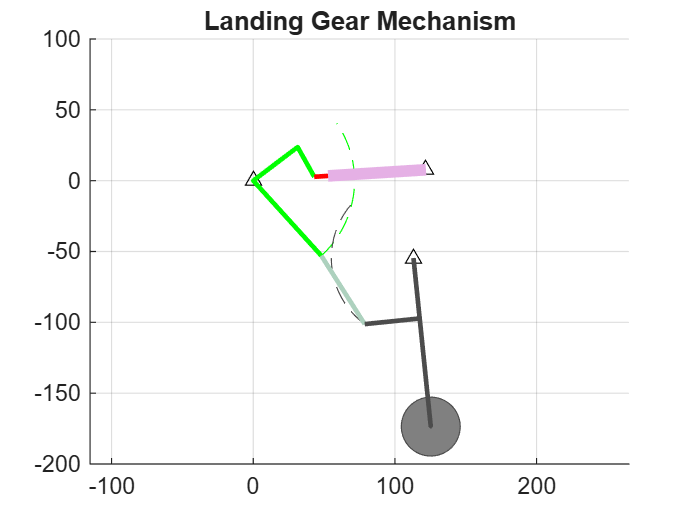

alpha = linspace(0, 2*pi, 50);
R_wheel = 20.8;

h_link2 = @(t) plot([subs(Cx,t) subs(Rx,t) O2x subs(ex,t)],[subs(Cy,t) subs(Ry,t) O2y subs(ey,t)],"-g", "LineWidth", 2);
h_link5 = @(t) plot([subs(ex,t) subs(fxNew,t)],[subs(ey,t) subs(fyNew,t)],"-", "Color", "#add1be", "LineWidth", 2);
h_link6 = @(t) plot(...
    [O6x subs(Px,t) subs(Qx,t) subs(fxNew,t)],...
    [O6y subs(Py,t) subs(Qy,t) subs(fyNew,t)],...
    "-", "Color", "#4c4c4c", "LineWidth", 2);
h_wheel = @(t) fill( ...
    [(subs(Px,t)) + R_wheel * cos(alpha)], ...
    [(subs(Py,t)) + R_wheel * sin(alpha)], ...
    [0.50 0.50 0.50], "EdgeColor", "#4c4c4c");

dist_O3C = @(t) sqrt((double(subs(Cx,t)) - O3x).^2 + (double(subs(Cy,t)) - O3y).^2);
joint_x = @(t) O3x + L_cyl * (double(subs(Cx,t)) - O3x) ./ dist_O3C(t);
joint_y = @(t) O3y + L_cyl * (double(subs(Cy,t)) - O3y) ./ dist_O3C(t);

h_act_cylinder = @(t) plot([O3x joint_x(t)], [O3y joint_y(t)], "-", "Color", "#e5b0e5", "LineWidth", 5);
h_act_piston   = @(t) plot([joint_x(t) double(subs(Cx,t))], [joint_y(t) double(subs(Cy,t))], "-r", "LineWidth", 2);

figure('Name', 'Landing Gear Mechanism with Actuator', 'Position', [100, 100, 800, 600]);
theta_to_plot = deg2rad(0:5:360);

hold on
theta_range = linspace(theta_start, theta_end, 100);
plot(O2x,O2y,"^k")
plot(O6x,O6y,"^k")
plot(O3x,O3y,"^k")
plot(subs(ex,theta_range),subs(ey,theta_range),"--g")
plot(subs(fxNew,theta_range),subs(fyNew,theta_range),"--", "Color", "#4c4c4c")

fanimator(h_link2,'AnimationRange',[theta_start theta_end])
fanimator(h_link5,'AnimationRange',[theta_start theta_end])
fanimator(h_link6,'AnimationRange',[theta_start theta_end])
fanimator(h_wheel,'AnimationRange',[theta_start theta_end])
fanimator(h_act_cylinder, 'AnimationRange', [theta_start theta_end])
fanimator(h_act_piston,   'AnimationRange', [theta_start theta_end])

hold off
axis equal
grid on
title('Landing Gear Mechanism');

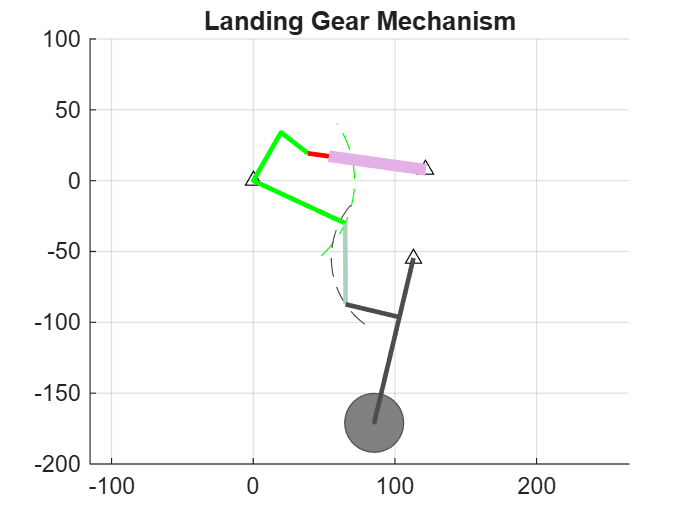

saveAVI = false;
if saveAVI
    exportAnimation('landing_gear.avi', 'FrameRate', 30);
end
playAnimation('FrameRate', 30, 'SpeedFactor', 0.2)